# **Creación de un autoencoder**

**lo primero que se hace es cargar los datos de entrenamiento del modelo neuronal.**

clc; clear all;

enable_Train = true;
data = load("X_train1.mat");
label = load("Y_train1.mat");

%Se importan los datos y las variables asociadas con los datos para el
%entrenamiento
data = data.x_train;
label = label.y_train;

size(label)

ans =          624          14           2       10000



[subport, simbolos, valor] = size(label)

subport = 624

simbolos = 14

valor = 20000


ratio = 0.75; %Porcentaje para la separación de los datos

[trainId,~,testId] = dividerand(1000,ratio,0.0,1-ratio);

x_train = data(:,:,:,trainId);
y_train = label(:,:,:,trainId);

x_val = data(:,:,:,testId);
y_val = label(:,:,:,testId);


x_train = cat(4, x_train(:,:,1,:), x_train(:,:,2,:));
y_train = cat(4, y_train(:,:,1,:), y_train(:,:,2,:));

x_test = cat(4, x_val(:,:,1,:), x_val(:,:,2,:));
y_test = cat(4, y_val(:,:,1,:), y_val(:,:,2,:));


inputSize = [624 16]

inputSize =    624    16



%autoenc = segnetLayers()

# Otra tipo de autoencoder

inputLayer = imageInputLayer([subport simbolos 1])

inputLayer =   ImageInputLayer with properties:

                      Name: ''
                 InputSize: [624 14 1]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: []



encodeLayers = [
    convolution2dLayer(5,8,Padding="same"), ... %624x14x8
    reluLayer,...
    maxPooling2dLayer(2,Padding="same", Stride = 1), ... %312x7x8
    convolution2dLayer(5,16,Padding="same"), ...% 312x7x16
    reluLayer,...
    maxPooling2dLayer(2,Padding="same", Stride = 1), ...
    convolution2dLayer(5,32,Padding="same"), ... %624x14x8
    reluLayer,...
    maxPooling2dLayer(2,Padding="same", Stride = 1), ... %312x7x8
    convolution2dLayer(5,64,Padding="same"), ...% 312x7x16
    reluLayer,...
    maxPooling2dLayer(2,Padding="same", Stride = 1), ...
    convolution2dLayer(5,128,Padding="same"), ...% 312x7x16
    reluLayer,...
    maxPooling2dLayer(2,Padding="same", Stride = 1), ...
]

encodeLayers =   1×15 Layer array with layers:

     1   ''   2-D Convolution   8 5×5 convolutions with stride [1  1] and padding 'same'
     2   ''   ReLU              ReLU
     3   ''   2-D Max Pooling   2×2 max pooling with stride [1  1] and padding 'same'
     4   ''   2-D Convolution   16 5×5 convolutions with stride [1  1] and padding 'same'
     5   ''   ReLU              ReLU
     6   ''   2-D Max Pooling   2×2 max pooling with stride [1  1] and padding 'same'
     7   ''   2-D Convolution   32 5×5 convolutions with stride [1  1] and padding 'same'
     8   ''   ReLU              ReLU
     9   ''   2-D Max Pooling   2×2 max pooling with stride [1  1] and padding 'same'
    10   ''   2-D Convolution   64 5×5 convolutions with stride [1  1] and padding 'same'
    11   ''   ReLU              ReLU
    12   ''   2-D Max Pooling   2×2 max pooling with stride [1  1] and padding 'same'
    13   ''   2-D Convol

decodeLayers = [
    transposedConv2dLayer(5,128, Stride=1,Cropping="same"),...
    reluLayer,...
    transposedConv2dLayer(5,64, Stride=1,Cropping="same"),...
    reluLayer,...
    transposedConv2dLayer(5,32, Stride=1,Cropping="same"),...
    reluLayer,...
    transposedConv2dLayer(5,16, Stride=1,Cropping="same"),...
    reluLayer,...
    transposedConv2dLayer(5,8, Stride=1, Cropping="same"),...
    reluLayer,...
    convolution2dLayer(1,1,Padding="same"), ... %624 x 16 x 
    regressionLayer
]

decodeLayers =   1×12 Layer array with layers:

     1   ''   2-D Transposed Convolution   128 5×5 transposed convolutions with stride [1  1] and cropping 'same'
     2   ''   ReLU                         ReLU
     3   ''   2-D Transposed Convolution   64 5×5 transposed convolutions with stride [1  1] and cropping 'same'
     4   ''   ReLU                         ReLU
     5   ''   2-D Transposed Convolution   32 5×5 transposed convolutions with stride [1  1] and cropping 'same'
     6   ''   ReLU                         ReLU
     7   ''   2-D Transposed Convolution   16 5×5 transposed convolutions with stride [1  1] and cropping 'same'
     8   ''   ReLU                         ReLU
     9   ''   2-D Transposed Convolution   8 5×5 transposed convolutions with stride [1  1] and cropping 'same'
    10   ''   ReLU                         ReLU
    11   ''   2-D Convolution              1 1×1 convolutions with str


%decodeLayers = regressionLayer;


% % SE GENERA EL AUTOENCODER CON LAS CAPAS
layers = [inputLayer, encodeLayers, decodeLayers]

layers =   1×28 Layer array with layers:

     1   ''   Image Input                  624×14×1 images with 'zerocenter' normalization
     2   ''   2-D Convolution              8 5×5 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                         ReLU
     4   ''   2-D Max Pooling              2×2 max pooling with stride [1  1] and padding 'same'
     5   ''   2-D Convolution              16 5×5 convolutions with stride [1  1] and padding 'same'
     6   ''   ReLU                         ReLU
     7   ''   2-D Max Pooling              2×2 max pooling with stride [1  1] and padding 'same'
     8   ''   2-D Convolution              32 5×5 convolutions with stride [1  1] and padding 'same'
     9   ''   ReLU                         ReLU
    10   ''   2-D Max Pooling              2×2 max pooling with stride [1  1] and padding 'same'
    11   ''   2-D Convolution              64 5×5 con

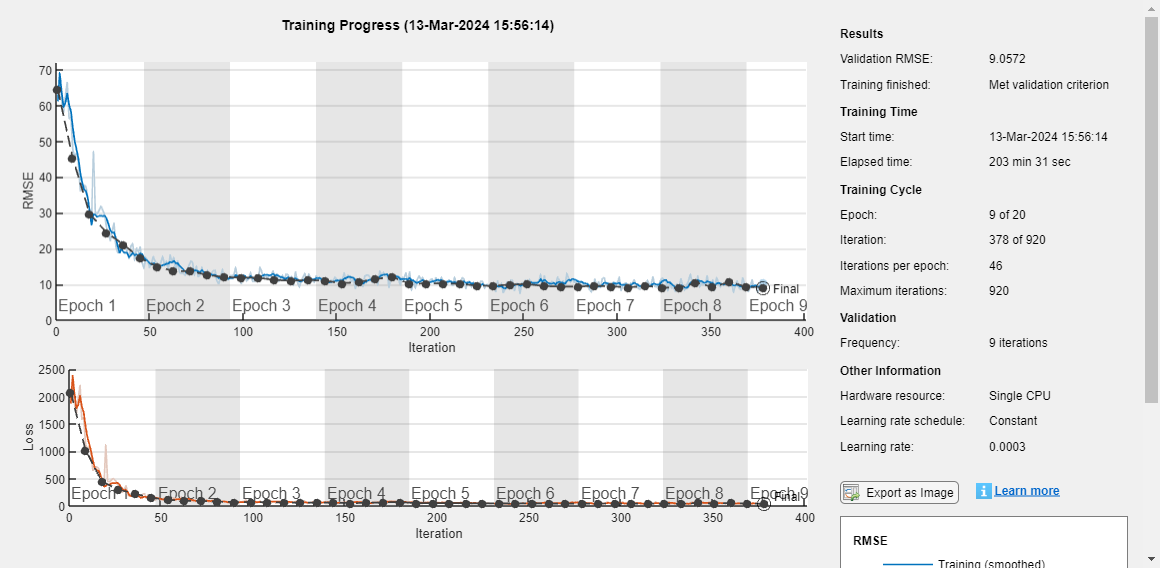

rng(42);

if enable_Train
    batch = 32; % Es el número de ejemplos que se introducen en la red.
    
    %Esta variable se usa para verificar 5 veces en cada época.
    valFrequency = round(size(x_train,4)/batch/5); 


    %Aquí se puede definir las capas que van a componer la RNA

    hiper_param = trainingOptions('adam', ...
        'InitialLearnRate',3e-4, ...
        'MaxEpochs',20, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'MiniBatchSize',batch, ...
        'ValidationData',{x_test, y_test}, ...
        'ValidationFrequency',valFrequency, ...
        'ValidationPatience',5);


    [estimacionRNA, infoRNA] = trainNetwork(x_train, ...
        y_train,layers,hiper_param);

    save('ModeloAutoencoder3.mat', "estimacionRNA");

else
    load("ModeloAutoencoder.mat");
end